# NB-IoT simulation

## transmission

%base message
length=100;
messageBits= randi([0 1],length,1)

messageBits =      1
     0
     1
     0
     1
     1
     1
     0
     0
     0


%map bits to symbols
messaggeGroupeds=reshape(messageBits,2,[])'%group by 2 bits

messaggeGroupeds =      1     0
     1     0
     1     1
     1     0
     0     0
     1     1
     1     1
     1     1
     1     0
     0     0


symbolMap=[1+1i, -1+1i, -1-1i, 1-1i] / sqrt(2); %normalized QPSK constellation points
messageSymbols = zeros(size(messaggeGroupeds, 1), 1);
for k = 1:size(messaggeGroupeds, 1)
    idx = bi2de(messaggeGroupeds(k, :), 'left-msb') + 1; %convert bit pair to decimal index
    messageSymbols(k) = symbolMap(idx); %symbolmap
end

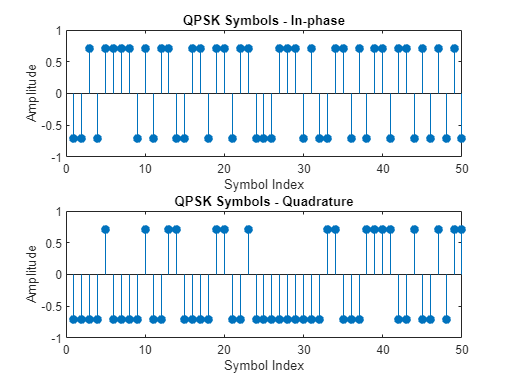

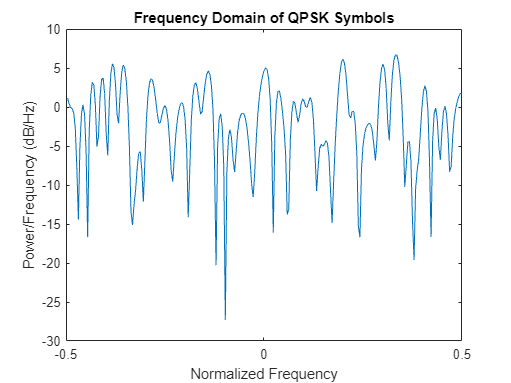


%plot time domain
figure;
subplot(2,1,1);
stem(real(messageSymbols), 'filled');
title('QPSK Symbols - In-phase');
xlabel('Symbol Index');
ylabel('Amplitude');
subplot(2,1,2);
stem(imag(messageSymbols), 'filled');
title('QPSK Symbols - Quadrature');
xlabel('Symbol Index');
ylabel('Amplitude');

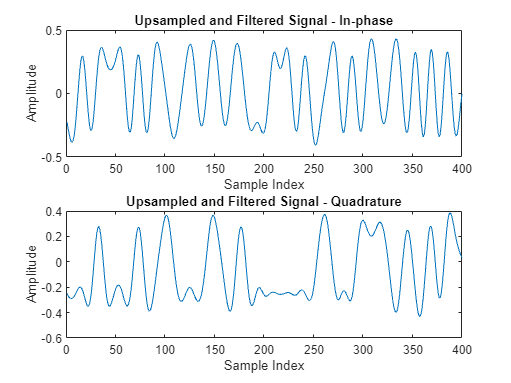


%upsample
bandwidth=180e3;
carrierFreq=890e6;
samplerate=bandwidth*2;

upsamplingFactor = 8; 
symbolsUpsampled = upsample(messageSymbols, upsamplingFactor);



%pulse shape filter (rrc)
span = 10; %flter span in symbols
rolloff = 0.25; %rolloff factor
sps = upsamplingFactor; %samples per symbol
rrcFilter = rcosdesign(rolloff, span, sps);
txSignal = conv(symbolsUpsampled, rrcFilter, 'same');

%plot time domain
figure;
subplot(2,1,1);
plot(real(txSignal));
title('Upsampled and Filtered Signal - In-phase');
xlabel('Sample Index');
ylabel('Amplitude');
subplot(2,1,2);
plot(imag(txSignal));
title('Upsampled and Filtered Signal - Quadrature');
xlabel('Sample Index');
ylabel('Amplitude');

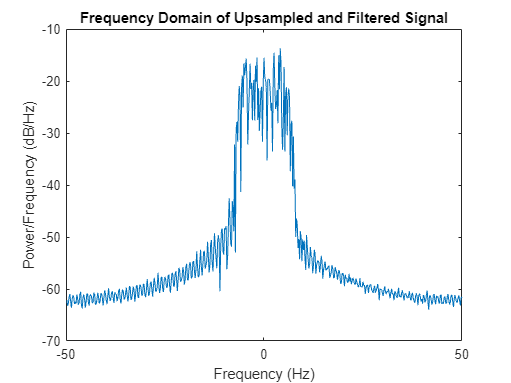


%plot frequency domain
figure;
[pxx, f] = periodogram(txSignal, [], [], 100, 'centered');
plot(f, 10*log10(pxx));
title('Frequency Domain of Upsampled and Filtered Signal');
xlabel('Frequency (Hz)');
ylabel('Power/Frequency (dB/Hz)');